# TPA 1 Grupo 10

A continuación se resuelve el trabajo de aplicación 1.

## Inciso 1

El rango admisible de la entrada/salida es de 5V.

## Inciso 2

Se hizo un código en c que permite generar una señal de PWM con ciclo de trabajo variable.

Con esta señal de entrada, se ingresó primero al 20% durante

clear;
close all;
s = tf('s');

TIME_DIFF = 1e-3;


## Se cargan los datos

% addpath('c:\Users\tomi\Github\facu3\Control 3\TPA\1');
% savepath;
data = open('prot_sim_data.dat');

## Se grafican los datos de la simulacion

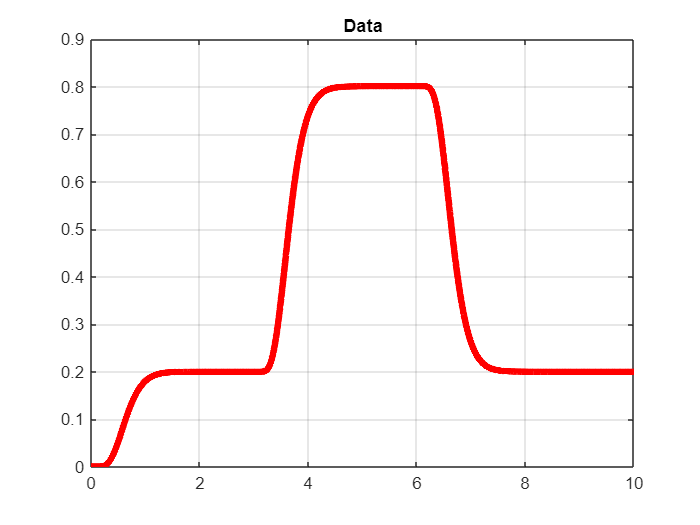

time = data.data(:,1);
y6 = data.data(:,7)/5; % se normaliza con respecto a 5V

figure();
plot(time, y6, 'r', 'linewidth', 4);
hold on;
grid on;
title('Data');

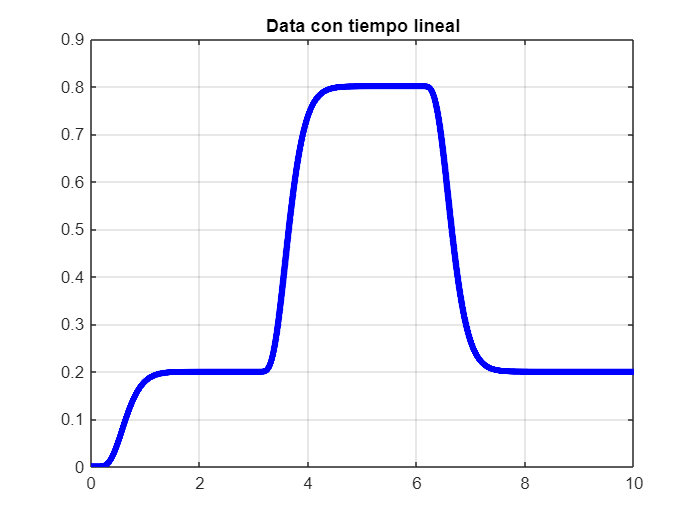


lineal_time = 0:TIME_DIFF:10;
lineal_y6 = interp1(time, y6, lineal_time);

figure;
plot(lineal_time, lineal_y6, 'b', 'linewidth', 4);
hold on;
grid on;
title('Data con tiempo lineal');

## Modelo FOPDT

MEAS_DELAY = 0.0753;

step_resp = lineal_y6((3/TIME_DIFF):(5/TIME_DIFF));
step_resp=step_resp-0.2; % muevo los datos 0.2 porque se comenzó con 20% de duty cycle
step_resp=step_resp/0.6; % escalo a que la referencia sea 1, porque se puso 80% de duty cycle como step
step_time = lineal_time(1:length(step_resp));
step_input = ones(1, length(step_resp));
for i=1:length(step_resp)
    step_input(i) = step_time(i) > MEAS_DELAY;
end

close all;
fig = figure;
set(fig, 'Toolbar', 'none', 'Menu', 'none');
plot(step_time, step_resp, 'b', 'linewidth', 6);
hold on;
grid on;
title('Respuesta al escalón (de 20% a 80% ciclo de trabajo)');
xlabel('Tiempo [Segundos]');
ylabel('Tensión normalizada (a 5V) [Volts]');
plot(step_time, step_input, '--r', 'linewidth', 2);

% De los graficos generados se estima el delay
fopdt_delay = 0.33791+MEAS_DELAY;
% De System Identification se obtuvieron los siguientes parámetros
fopdt_time_constant = 0.28802;
fopdt_gain = 1;

% Modelo FOPDT resultante
fopdt_estimated = fopdt_gain/(s*fopdt_time_constant+1);
fopdt_estimated.inputDelay = fopdt_delay;

[fopdt_est_y, fopdt_est_t] = step(fopdt_estimated, step_time); fopdt_est_y=reshape(fopdt_est_y, size(step_resp));
plot(fopdt_est_t, fopdt_est_y, 'k', 'linewidth', 2);
error_fopdt = immse(step_resp, fopdt_est_y);
fprintf('El error cuadrático medio entre la estimada y los datos es: %f\n', error_fopdt);

El error cuadrático medio entre la estimada y los datos es: 0.001007


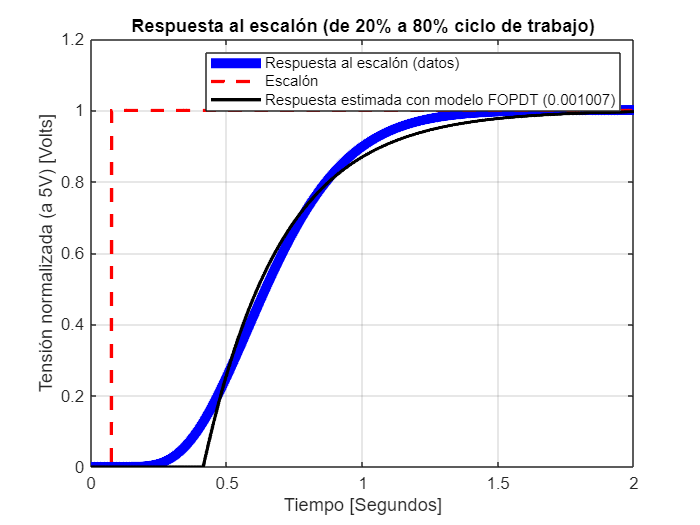

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt));

## Modelo SOPDT

% Parámetros obtenidos de System Identification
sopdt_delay = 0.3272;
sopdt_time_constant_1 = 0.1798;
sopdt_time_constant_2 = 5;
sopdt_gain = 1;

% Modelo FOPDT resultante
sopdt_estimated = sopdt_gain/((s*sopdt_time_constant_1+1)*(s*sopdt_time_constant_1+1));
sopdt_estimated.inputDelay = sopdt_delay;

[sopdt_est_y, sopdt_est_t] = step(sopdt_estimated, step_time); sopdt_est_y=reshape(sopdt_est_y, size(step_resp));
plot(sopdt_est_t, sopdt_est_y, 'm', 'linewidth', 2);

error_sopdt = immse(step_resp, sopdt_est_y);
fprintf('El error cuadrático medio (SOPDT) entre la estimada y los datos es: %f\n', error_sopdt);

El error cuadrático medio (SOPDT) entre la estimada y los datos es: 0.000259



fprintf('La mejora del modelo SOPDT contra FOPDT es de "%f%%"\n', (error_fopdt-error_sopdt)/error_fopdt);

La mejora del modelo SOPDT contra FOPDT es de "0.742461%"


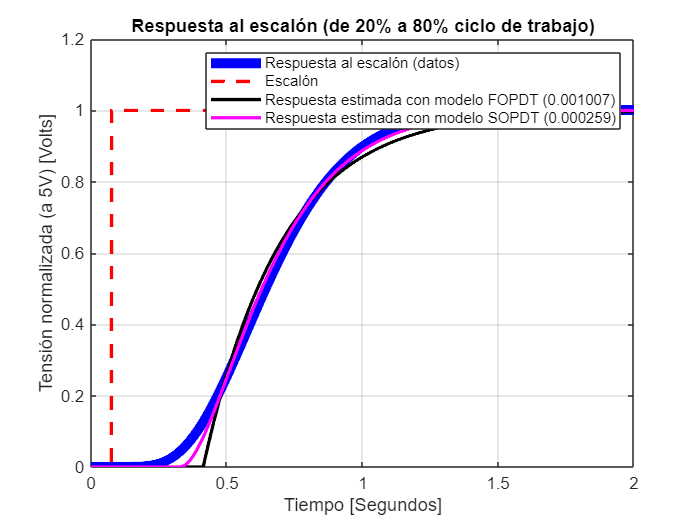

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt), sprintf('Respuesta estimada con modelo SOPDT (%f)', error_sopdt));

## Modelo de las ecuaciones en diferencias

Modelo completo a partir de las ecuaciones en diferencias

Tiene un retardo porque el micro tiene un retardo cuando actúa

R1=10e3;
C1=10e-6;
complete_model = 1/((R1*C1*s+1)^6);
complete_model.InputDelay = 0.0753;

[ec_diff_y, ec_diff_t] = step(complete_model, step_time); ec_diff_y=reshape(ec_diff_y, size(step_resp));
plot(ec_diff_t, ec_diff_y, 'g', 'linewidth', 2);

error_ec_diff = immse(step_resp, ec_diff_y);
fprintf('El error cuadrático medio (SOPDT) entre la estimada y los datos es: %f\n', error_ec_diff);

El error cuadrático medio (SOPDT) entre la estimada y los datos es: 0.000001


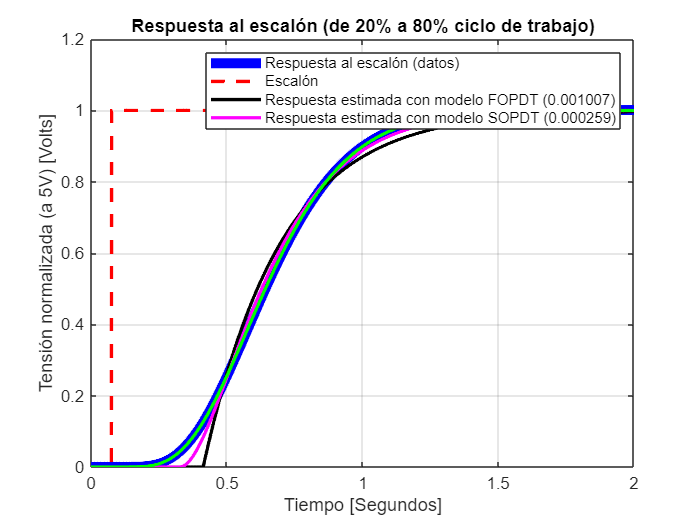

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt), sprintf('Respuesta estimada con modelo SOPDT (%f)', error_sopdt));

## Modelo de alto orden con System Identification

high_order_model = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06);

[high_y, high_t] = step(high_order_model, step_time); high_y=reshape(high_y, size(step_resp));
close all;
plot(step_time, step_resp, 'b', 'linewidth', 2);
hold on;
grid on;
plot(step_time, step_input, '--r', 'linewidth', 2);
plot(high_t, high_y, 'g', 'linewidth', 2);

error_high = immse(step_resp, high_y);
fprintf('El error cuadrático medio (alto orden) entre lo estimado y los datos es: %f\n', error_high);

El error cuadrático medio (alto orden) entre lo estimado y los datos es: 0.003522


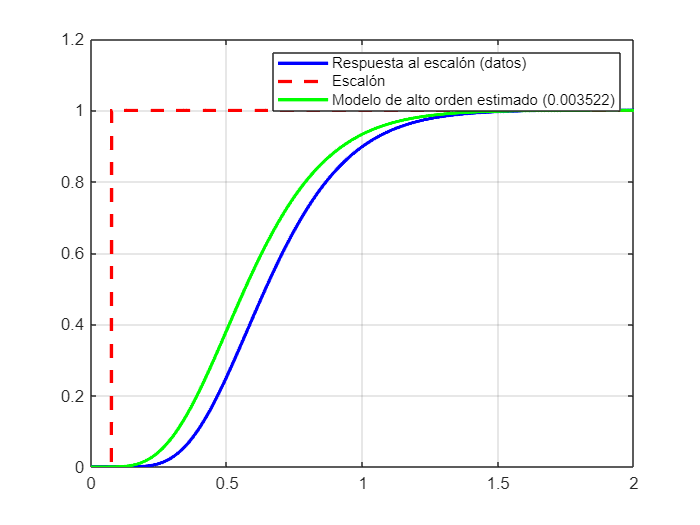

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Modelo de alto orden estimado (%f)', error_high));

## Señal PRBS

data_prbs = open('prot_sim_data_prbs.dat');

## Extraigo los datos de la simulación

El ensaño se hace un 7 bits y considerando un tiempo de rising de 2 segundos. Por lo que el ensayo debería durar TEST_DURATION segundos

IMPORTANTE ARREGLAR LA FRECUENCIA DE MUESTREO, tiene que se como 10 veces más grande

BITS=7;
SAMPLING_TIME=1.4/BITS

SAMPLING_TIME = 0.2000

TEST_DURATION=(2^BITS-1)*SAMPLING_TIME

TEST_DURATION = 25.4000

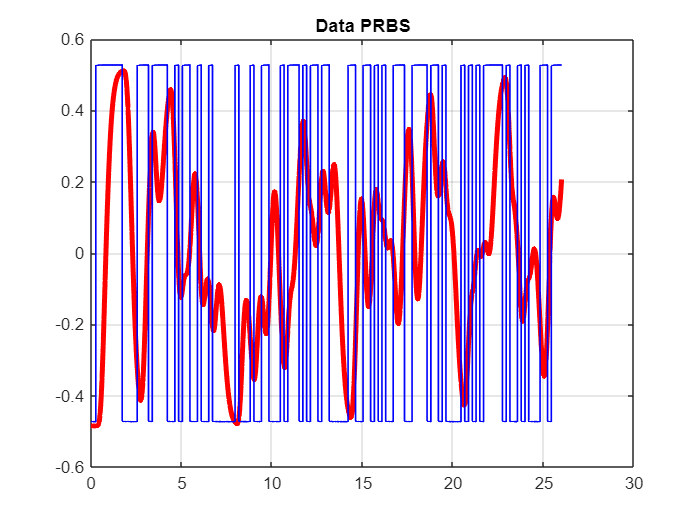

MAX_TIME=26;

DIEZMADO_POR = 10;

time_prbs = data_prbs.data(:,1);
pwm_prbs = data_prbs.data(:,2)/5;  % divido por 5 para normalizar los datos con respecto al pico de 5v
y6_prbs = data_prbs.data(:,3)/5; % divido por 5 para normalizar los datos con respecto al pico de 5v

pwm_prbs = pwm_prbs - mean(pwm_prbs);
y6_prbs = y6_prbs - mean(y6_prbs);

figure();
plot(time_prbs, y6_prbs, 'r', 'linewidth', 3);
hold on;
grid on;
title('Data PRBS');
plot(time_prbs, pwm_prbs, 'b', 'linewidth', 1);

lineal_time_prbs = 1:(1/6):(MAX_TIME-1/6);
lineal_pwm_prbs = interp1(time_prbs(1:DIEZMADO_POR:length(time_prbs)), pwm_prbs(1:DIEZMADO_POR:length(time_prbs)), lineal_time_prbs)

lineal_pwm_prbs =     0.5271    0.5271    0.5271    0.5271    0.5271   -0.4722   -0.4727   -0.4728   -0.4728    0.2426    0.5265    0.5270    0.5271   -0.3429   -0.4246    0.5266    0.5270    0.5271    0.4741   -0.2510   -0.4722   -0.4727    0.5256   -0.0434    0.1094    0.5266    0.5270   -0.4714   -0.4726   -0.4728    0.5265   -0.4720   -0.4727   -0.4728    0.5267   -0.4723   -0.4726   -0.4728   -0.4728   -0.4729   -0.4729   -0.4729    0.5258    0.5269   -0.4725   -0.4727   -0.4058    0.5257   -0.2758   -0.4725


lineal_y6_prbs = interp1(time_prbs(1:DIEZMADO_POR:length(time_prbs)), y6_prbs(1:DIEZMADO_POR:length(time_prbs)), lineal_time_prbs)

lineal_y6_prbs =     0.2197    0.3943    0.4543    0.4936    0.5059    0.5105    0.4418    0.2251   -0.0527   -0.2608   -0.3924   -0.3839   -0.1814    0.0914    0.2980    0.3147    0.1880    0.1927    0.2561    0.3682    0.4472    0.4198    0.2082   -0.0493   -0.1093   -0.0671   -0.0456    0.0440    0.1944    0.1901    0.0062   -0.1428   -0.1053   -0.0840   -0.1779   -0.2027   -0.1556   -0.1166   -0.2260   -0.3391   -0.3900   -0.4409   -0.4773   -0.4634   -0.3194   -0.2311   -0.1541   -0.2643   -0.3541   -0.2704



mean(lineal_pwm_prbs)

ans = 0.0372

mean(lineal_y6_prbs)

ans = 0.0150

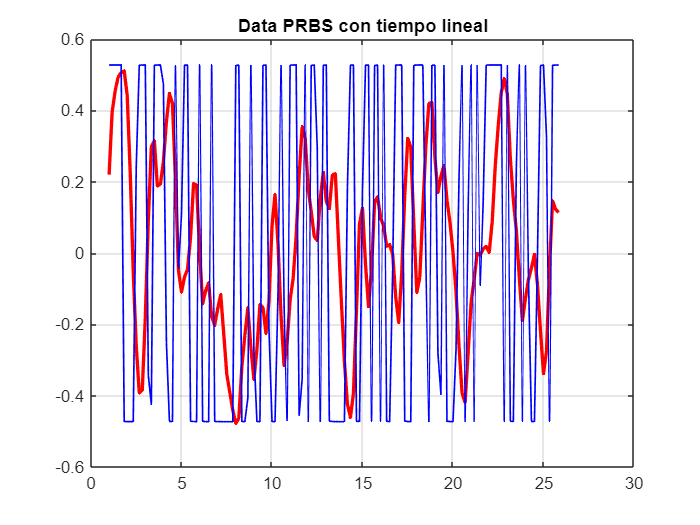


figure;
plot(lineal_time_prbs, lineal_y6_prbs, 'r', 'linewidth', 2);
hold on;
grid on;
title('Data PRBS con tiempo lineal');
plot(lineal_time_prbs, lineal_pwm_prbs, 'b', 'linewidth', 1);

## Transformada de fourier de la PRBS

fft_pwm = fft(lineal_pwm_prbs, length(lineal_pwm_prbs))

fft_pwm =    5.5828 + 0.0000i   5.3603 + 7.2468i   6.7507 - 0.0616i   1.6949 - 4.2942i  -5.9311 - 0.2473i   3.6515 - 2.0899i   5.0672 + 1.5686i  10.2469 + 4.1453i  -3.6148 + 4.9132i   3.3223 + 1.2088i   2.5304 + 3.2187i   4.9543 - 0.7424i   0.8127 - 0.9867i   7.0120 - 3.7322i   2.5024 + 0.7572i   1.6634 - 0.2947i  -7.3953 - 1.4697i   3.9340 + 3.6711i   0.2862 - 9.2814i   5.1114 - 9.1537i  -2.8749 - 0.6631i  -3.6472 - 9.8093i   1.0511 - 0.4721i  -2.9342 + 4.5311i  -4.0726 + 5.6740i   6.1605 + 2.1647i   0.9382 + 8.1698i  -0.6847 - 3.2223i   2.0747 + 7.2571i   0.5040 + 3.1316i  -1.7668 - 6.9436i  -1.4768 + 6.5935i   3.2567 - 2.3941i -11.9433 + 2.7671i  -2.7207 + 3.7838i   6.9490 + 1.8189i  -1.9224 - 6.0228i  -5.4822 + 3.6355i  -5.1678 - 4.6627i   5.2413 + 3.9079i   2.4005 - 1.5315i   0.8630 - 1.3463i   5.1263 - 4.4355i  -2.8566 - 0.9047i   1.3248 + 5.2102i  -4.7167 - 2.1443i   2.1584 + 3.0953i  -5.6337 + 0.3592i  -0.8162 - 5.1364i   7.1580 - 5.2138i


fft_y6 = fft(lineal_y6_prbs, length(lineal_y6_prbs))

fft_y6 =    2.2478 + 0.0000i   4.7078 + 5.3244i   5.2586 - 4.1652i  -1.5643 - 6.9565i  -4.0261 + 6.1822i  -0.4067 - 4.0962i   3.5892 - 4.5415i   8.7416 - 5.8397i   5.6209 + 4.2676i   3.4674 - 3.8398i   1.1925 - 3.5354i  -1.1235 - 4.3217i  -0.0683 - 2.0845i  -5.7999 - 1.7632i   0.8578 - 2.2763i  -1.6893 - 1.6140i   3.1151 + 2.8815i  -0.2001 - 2.3738i  -1.9217 + 4.7290i  -3.7366 + 3.3924i   1.5726 - 0.0812i   2.0698 + 3.9017i   0.2718 - 0.3788i  -0.1465 - 0.8367i   0.6723 - 1.6408i  -2.1634 + 0.5334i  -1.9604 - 1.6697i   1.1158 + 0.7677i  -2.0765 - 0.7535i  -0.6392 - 0.8057i   1.4640 + 0.2342i  -1.0088 - 1.1219i   0.6461 + 0.7787i  -0.1733 - 1.6611i  -0.4555 - 0.9926i  -0.4052 + 0.6855i   0.9134 - 0.2971i  -0.6924 - 0.7986i   0.2033 - 1.1071i  -0.5424 - 0.0278i   0.0778 + 0.3079i   0.3891 + 0.1583i   0.8082 + 0.1534i  -0.0177 - 0.2895i  -0.3471 + 0.4439i   0.0130 - 0.5206i  -0.0701 + 0.2856i  -0.2440 - 0.1411i   0.2889 - 0.2303i   0.3847 - 0.0448i


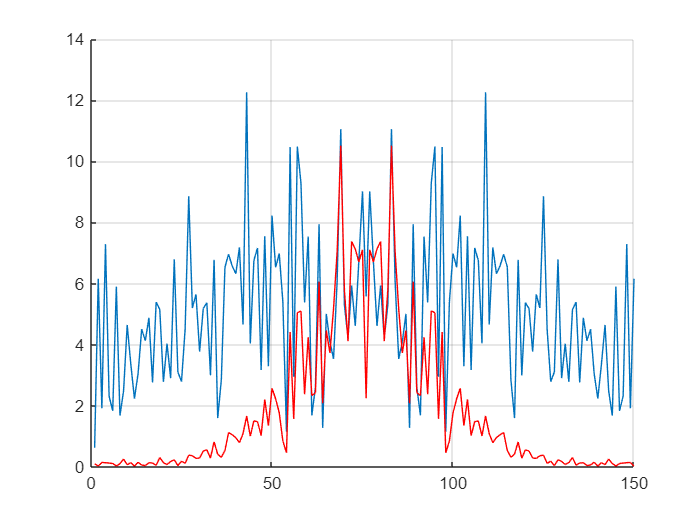


figure; grid on; hold on;
plot(abs(fftshift(fft_pwm)))
plot(abs(fftshift(fft_y6)), 'r')

sxx = abs(fft_pwm).^2;
syy = abs(fft_pwm).^2;
ssys = syy/sxx;

plot(ssys, 'k', 'linewidth', 3);

## TPA 2

K=0.5;
a=0.28802;
PI1 = K*(a*s+1)/s;

fopdt_estimated.InputDelay = 0;
CL1 = fopdt_estimated/(1+fopdt_estimated*PI1);

[pid_y, pid_x] = step(CL1);

figure;
plot(pid_x, pid_y, 'r', 'linewidth', 3);
xlabel('Tiempo [segundos]');
ylabel('Amplitud normalizada [Volts]');